## Autonomie - Traitement du Signal 

## Estimation du milieu oceanique

Triboulet Corentin

### Question 7

Tracez et interpretez la fonction d'autocorrelation d'un signal MLF pour differentes valeurs de T puis de B.


T=[10,50,100];
B=[10,50,100];
t=10;
tau=linspace(-t,t,1000);

B1=1;
for t=T
    plot(tau,t.*tri(tau/t).*sinc(B1.*tri(tau/t).*tau))
    legend('T=10','T=50','T=100')
    hold on
end

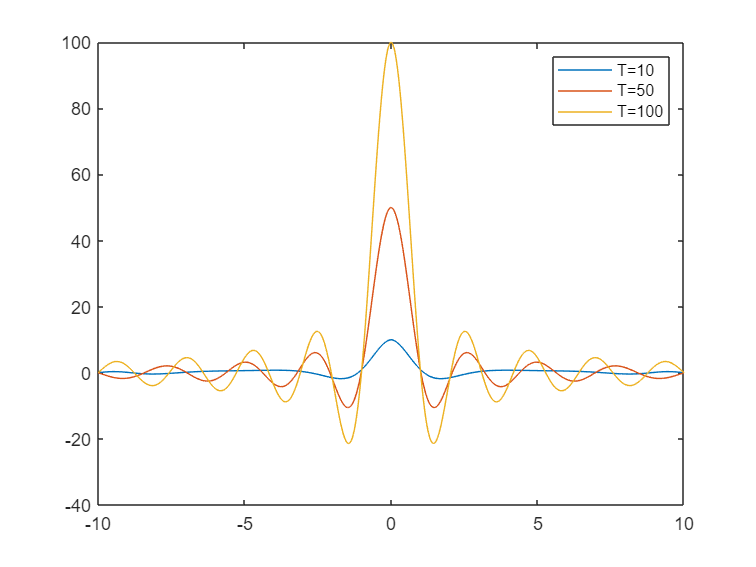

hold off


T1=10;
for b=B
    plot(tau,T1*tri(tau/T1).*sinc(b.*tri(tau/T1).*tau))
    legend('B=10','B=50','B=100')
    hold on
end

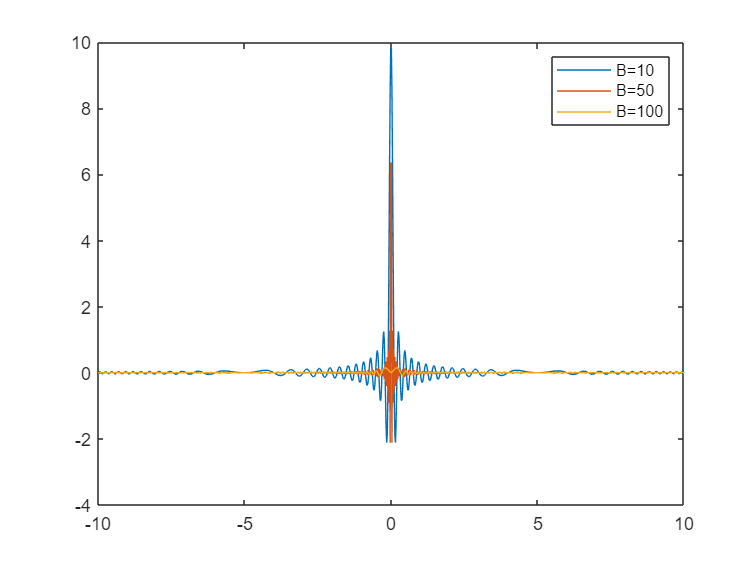

hold off

### Question 8

Construisez le vecteur des echantillons {xk}_{k=0:N-1} associe au signal MLF x dont vous fixerez les parametres T et B en accord avec une frequence d'echantillonnage Ts de 10^{-4} sec. 

Ts = 10^(-4); periode d'echantillonnage

Ts=0.0001;
T=0.2;
N=T/Ts;
B=2000;
f=inline('sin(pi*B/T*t.^2)')

f =

     Inline function:
     f(B,T,t) = sin(pi*B/T*t.^2)



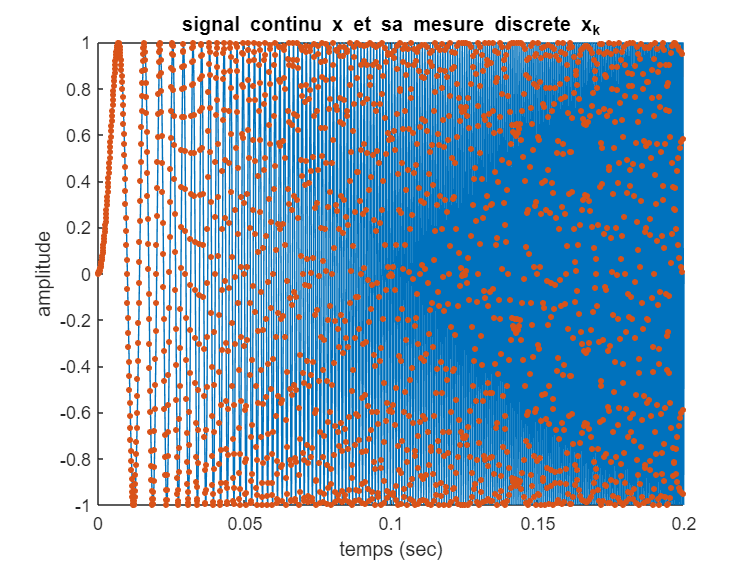


% Calcul du signal analogique x
t = 0:Ts/100:T;
x_lim = f(B,T,t);

% Calcul des N échantillons du signal mesuré xk
tk = 0:Ts:(N-1)*Ts;
xk = f(B,T,tk);

figure,
plot(t, x_lim); hold on;
plot(tk, xk, '.','MarkerSize',10); hold off;
xlabel('temps (sec)');
ylabel('amplitude');
title('signal continu x et sa mesure discrete x_k');

### Question 9

Calculez N échantillons de la transformee de Fourier X du signal continu x. Calculez sa fonction d'autocorrélation Rx et évaluez la densité spectrale Sx du signal de deux façons differentes.

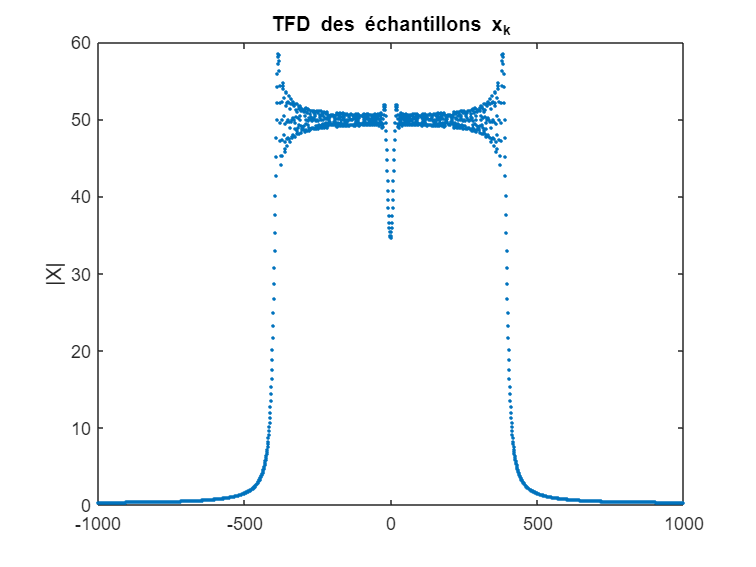

X=fftshift(fft(xk));
figure 
plot(linspace(-N/2,N/2-1,N),abs(X), '.');
ylabel('|X|');
title('TFD des échantillons x_k');

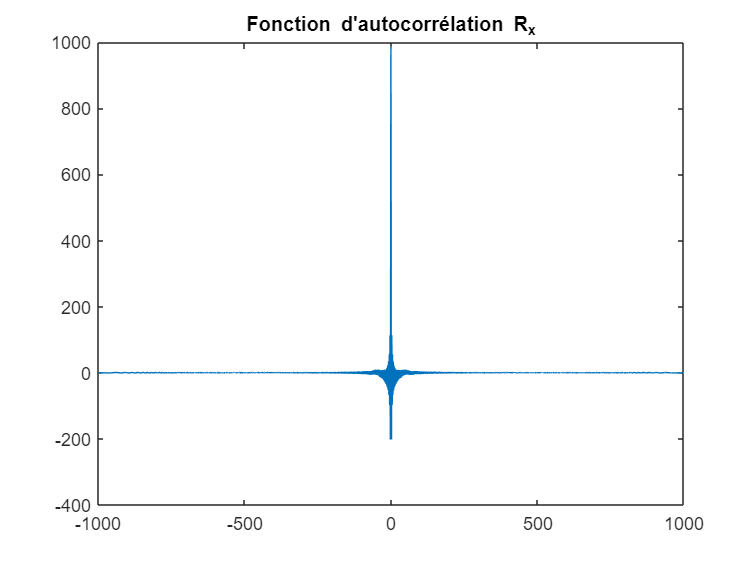


Rx=xcorr(xk);

figure
plot(linspace(-N/2,N/2-1,2*N-1),Rx)
title("Fonction d'autocorrélation R_x")

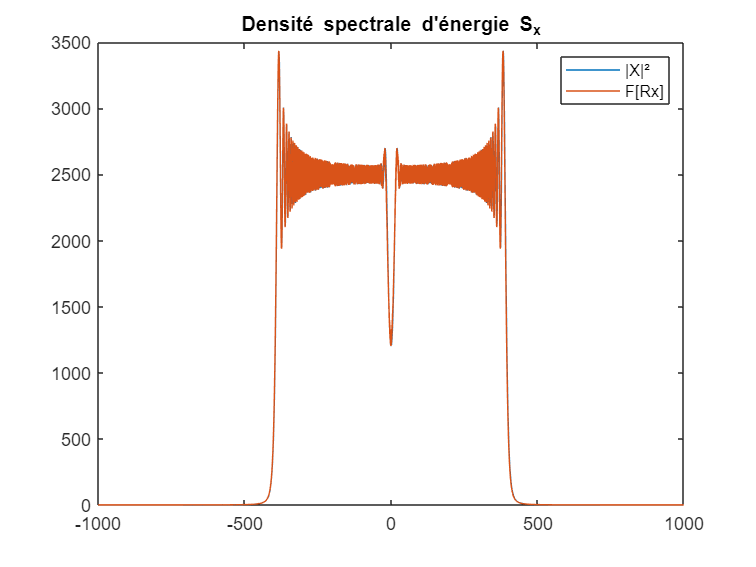


Sx1=abs(X).^2;
Sx=Sx1;
Sx2=abs(fftshift(fft(Rx)));
figure
plot(linspace(-N/2,N/2-1,N),Sx1,linspace(-N/2,N/2-1,2*N-1),Sx2)
legend('|X|²','F[Rx]')
title("Densité spectrale d'énergie S_x")

### Question 12

Construisez le vecteur des echantillons {bk}_{k=0:N-1} associe a une realisation b d'un bruit blanc, gaussien, echantillonne a la periode Ts=10^{-4} sec et de duree T.

Ts = 10^(-4); % periode d'echantillonnage (sec)

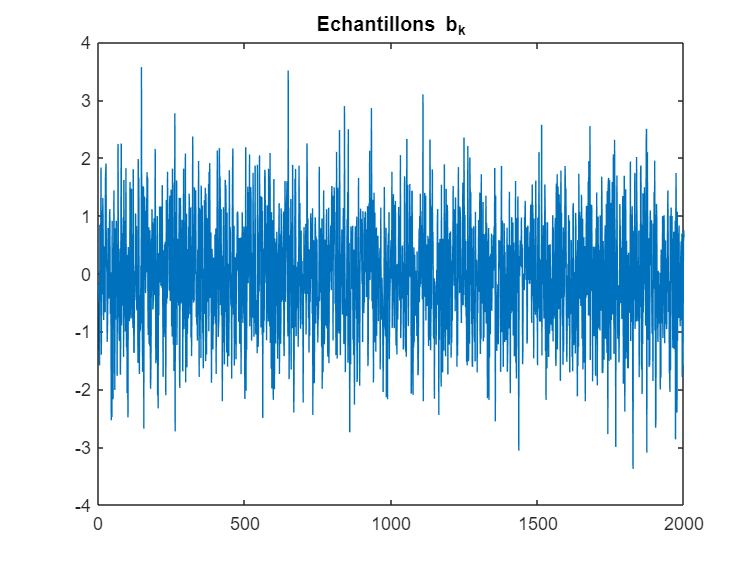

Ts=0.0001;
T=0.2;
N=T/Ts;
bk=randn(1,N);
plot(bk)
title('Echantillons b_k')

### Question 13

Calculez la transformee de Fourier, la fonction d'autocorrelation et la densite spectrale de cette realisation b.

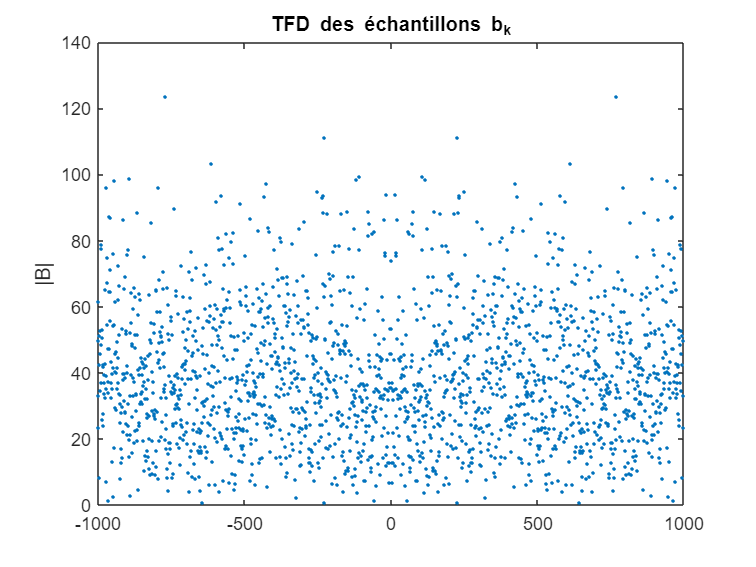

B=fftshift(fft(bk));
figure 
plot(linspace(-N/2,N/2-1,N),abs(B), '.');
ylabel('|B|');
title('TFD des échantillons b_k');

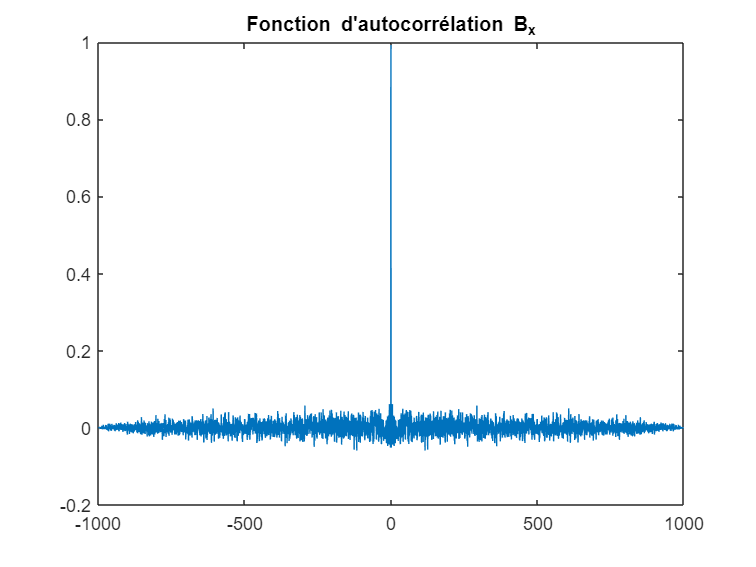

Bx=xcorr(bk,bk)/N;
figure
plot(linspace(-N/2,N/2-1,2*N-1),Bx)
title("Fonction d'autocorrélation B_x")

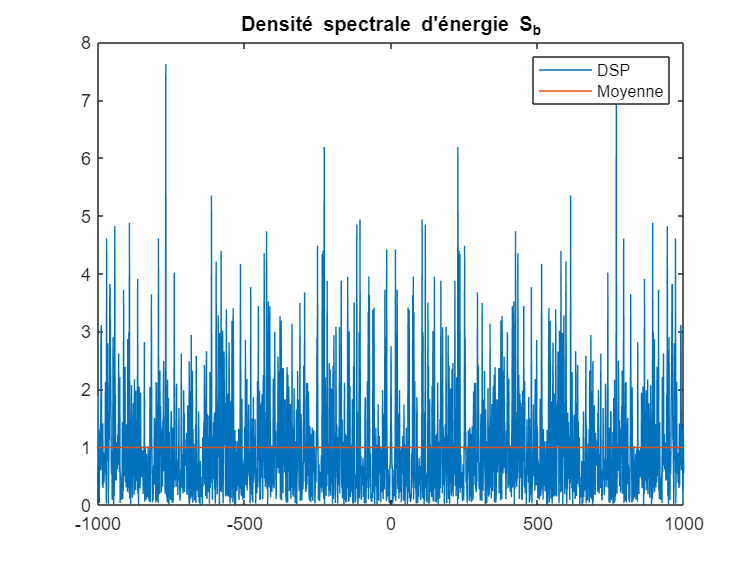

Sb=abs(B).^2/N;
figure
plot(linspace(-N/2,N/2-1,N),Sb)
hold on

M=mean(Sb);
plot([-N/2,N/2],[M,M])
legend('DSP','Moyenne')
title("Densité spectrale d'énergie S_b")
hold off

### Question 14

Realisez un filtre et appliquez le au signal b afin de limiter son support spectral a l'intervalle [0;B] Hz. Representez le signal x obtenu en sortie du filtre, sa transformee de Fourier, sa fonction d'autocorrelation et sa densite spectrale d'energie.

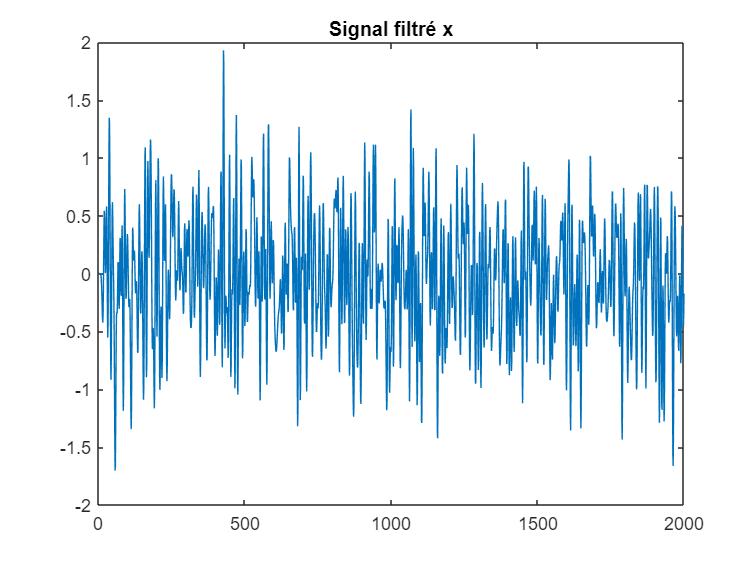

B=2000;
tcont = [0:N-1]*Ts; % vecteur des temps "continus"
nuc = 1400; % frequence de coupure (Hz)
ordre = 15; % ordre du filtre
nucont = [-N/2:N/2-1]/(Ts*N);    % vecteur des fréquences (centre sur 0)
[D,C] = butter(ordre,2*pi*nuc,'s');
x_lim= lsim(tf(D,C),bk,tcont);
x_lim=x_lim';
X = fftshift(Ts*fft(x_lim));

figure
plot(x_lim)
title('Signal filtré x')

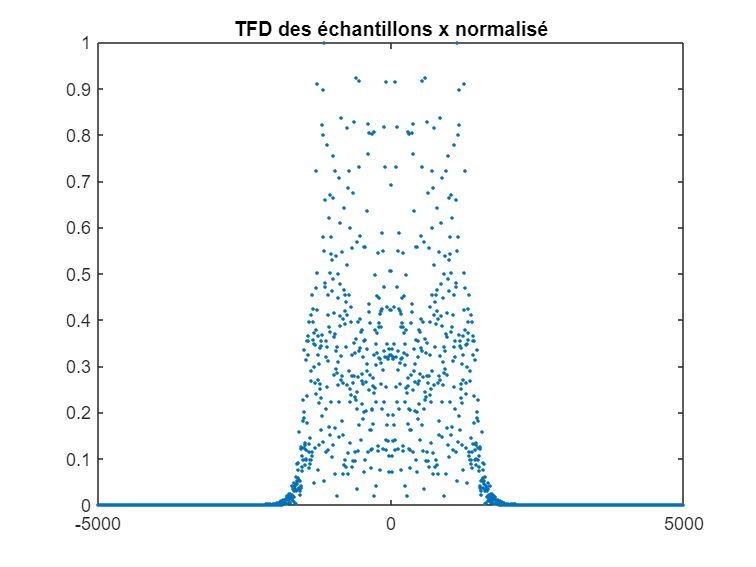

figure
plot(nucont,abs(X)/max(abs(X)),'.')
title('TFD des échantillons x normalisé')

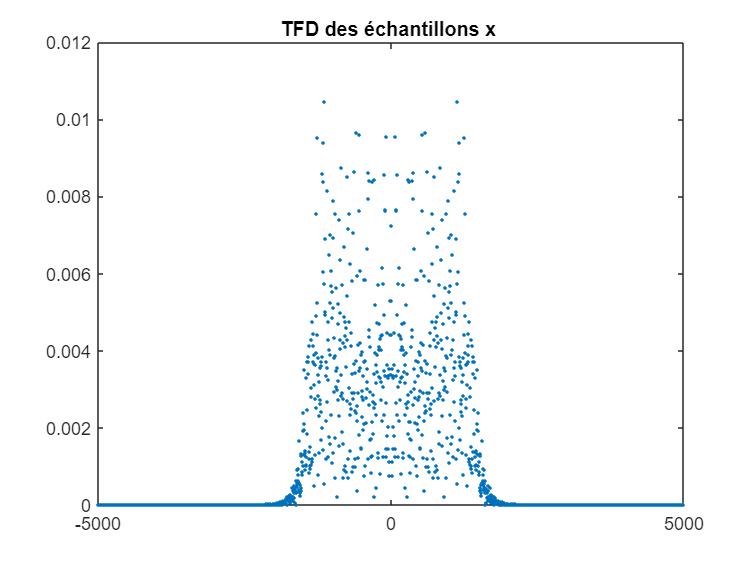

figure 
plot(nucont,abs(X),'.')
title('TFD des échantillons x ')

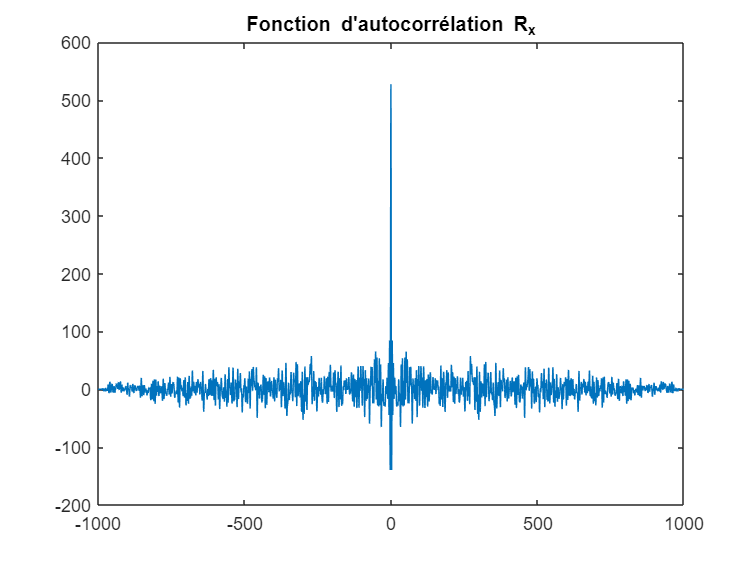

Rx_lim=xcorr(x_lim);
figure
plot(linspace(-N/2,N/2-1,2*N-1),Rx_lim)
title("Fonction d'autocorrélation R_x")

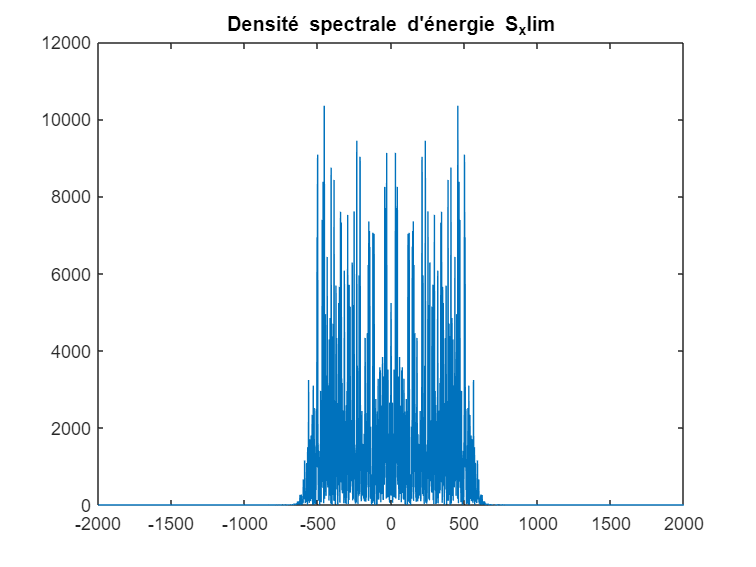


Sx_lim=fftshift(fft(Rx_lim));
figure
plot(linspace(-N+1,N-1,2*N-1),abs(Sx_lim))
title("Densité spectrale d'énergie S_xlim")

### Question 15

Observez le signal reçu apres propagation ainsi que son spectre.

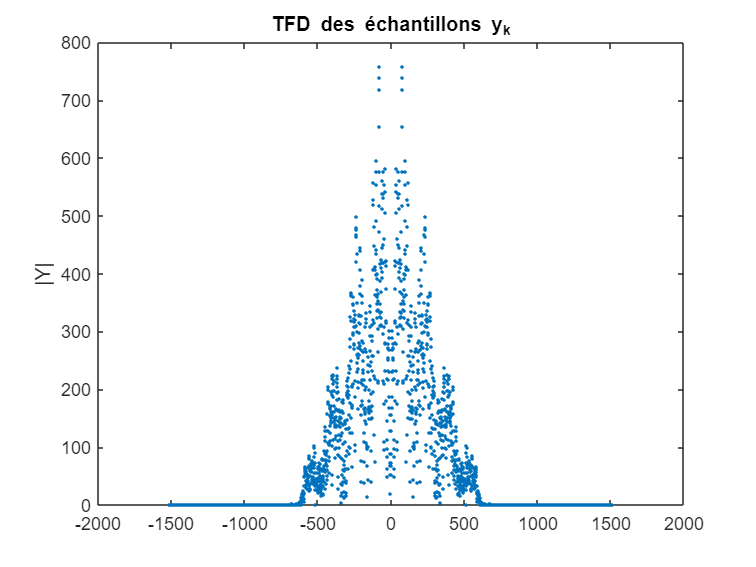

sim('Ocean');   % lance le modele simulink 'Ocean.mdl'
yk = yk(:)';    % mise sous forme de vecteur ligne
Y=fftshift(fft(yk));
n=length(Y);
figure 
plot(linspace(-n/2,n/2-1,n),abs(Y), '.');
ylabel('|Y|');
title('TFD des échantillons y_k');

### Question 16

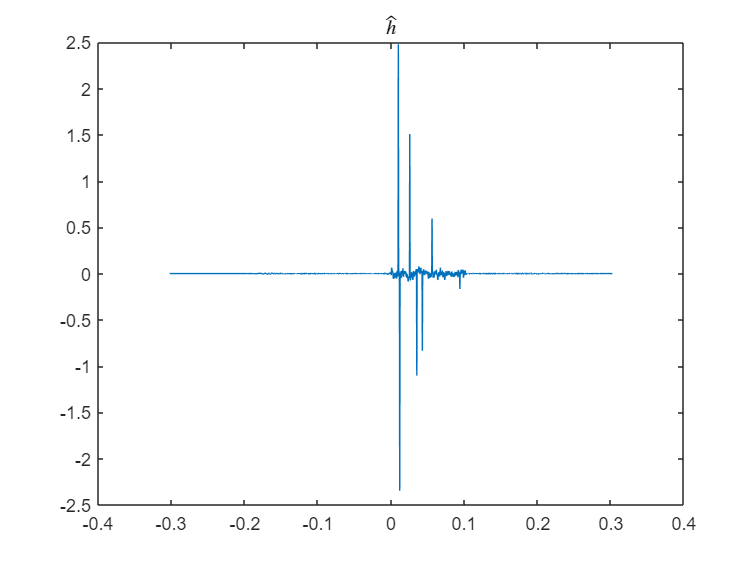

tk = 0:Ts:(N-1)*Ts;
xk = f(B,T,tk);
Rxy=xcorr(yk,xk);
h=Rxy/Rx(N);
figure 
n2=length(h);
plot(Ts*linspace(-n2/2,n2/2-1,n2),h);
title('$\hat{h}$','interpreter','latex');


$$\tau_1=0,00995s
$$



$$\tau_2=0,01185s$$



$$\tau_3=0,02555s$$


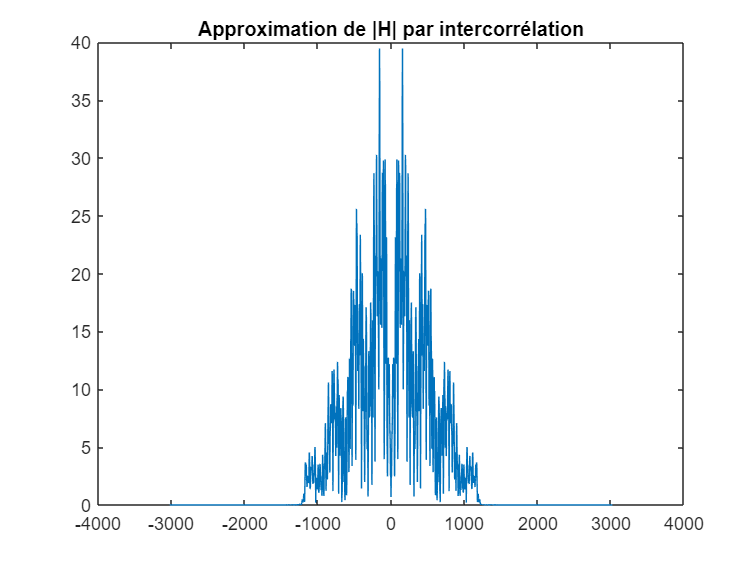

H=fftshift(fft(h)); 
n1=length(H);
figure
plot(linspace(-n1/2,n1/2-1,n1),abs(H))
title("Approximation de |H| par intercorrélation")

### Question 17

Estimez la reponse impulsionnelle du milieu pour quelques valeurs des parametres T et B du signal. Observez, comparez et interpretez les resultats.

#### Signal sinusoidal

Ts=0.0001;
T=0.2;
N=T/Ts;
Liste_B=[1000,2000,4000];
Liste_T=[0.1,0.2,0.5];
f=inline('sin(pi*B/T*t.^2)')

f =

     Inline function:
     f(B,T,t) = sin(pi*B/T*t.^2)



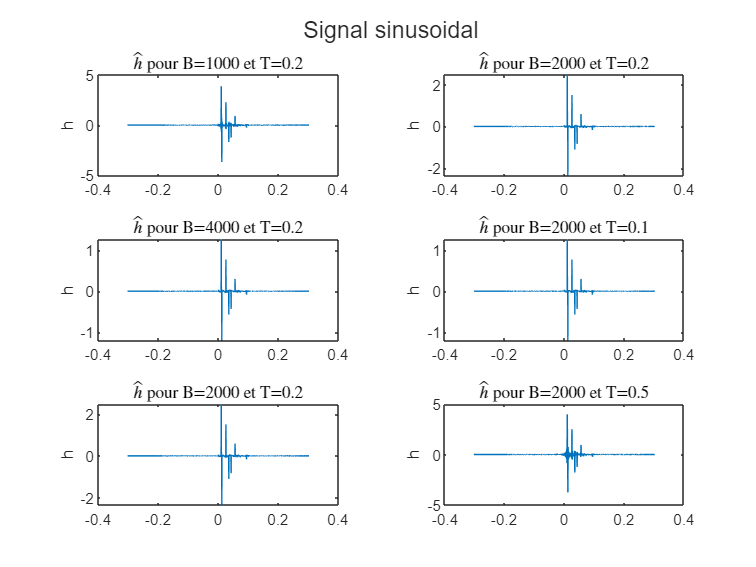

t1=tiledlayout(3,2);
title(t1,'Signal sinusoidal')
for i=Liste_B
    nexttile
    % Calcul des N échantillons du signal mesuré xk
    tk = 0:Ts:(N-1)*Ts;
    xk = f(i,T,tk);
    sim('Ocean');   % lance le modele simulink 'Ocean.mdl'
    yk = yk(:)';    % mise sous forme de vecteur ligne
    Rxy=xcorr(yk,xk);
    Sxy=fftshift(fft(Rxy));
    h=Rxy/Rx(N);
    n2=length(h);
    plot(Ts*linspace(-n2/2,n2/2-1,n2),h);
    ylabel('h');
    title(['$\hat{h}$ pour B=',num2str(i),' et T=',num2str(T)],'interpreter','latex');
end

for i=Liste_T
    nexttile
    % Calcul des N échantillons du signal mesuré xk
    tk = 0:Ts:(N-1)*Ts;
    xk = f(B,i,tk);
    sim('Ocean');   % lance le modele simulink 'Ocean.mdl'
    yk = yk(:)';    % mise sous forme de vecteur ligne
    Rxy=xcorr(yk,xk);
    Sxy=fftshift(fft(Rxy));
    h=Rxy/Rx(N);
    n2=length(h);
    plot(Ts*linspace(-n2/2,n2/2-1,n2),h);
    ylabel('h');
    title(['$\hat{h}$ pour B=',num2str(B),' et T=',num2str(i)],'interpreter','latex');
end

#### Signal avec bruit blanc 

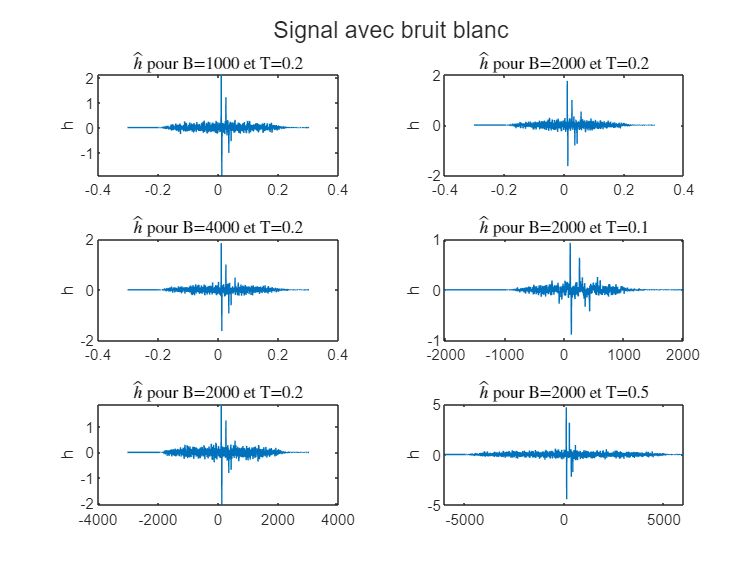

Ts=0.0001;
T=0.2;
N=T/Ts;
Liste_B=[1000,2000,4000];
Liste_T=[0.1,0.2,0.5];
t2=tiledlayout(3,2);
title(t2,'Signal avec bruit blanc')
for i=Liste_B
    nexttile
    % Calcul des N échantillons du signal mesuré xk
    Ts=0.0001;
    N1=T/Ts;
    xk=randn(1,N1);
    tk = 0:Ts:(N1-1)*Ts;
    sim('Ocean');   % lance le modele simulink 'Ocean.mdl'
    yk = yk(:)';    % mise sous forme de vecteur ligne
    Rxy=xcorr(yk,xk);
    Sxy=fftshift(fft(Rxy));
    h=Rxy/Rx(N);
    n2=length(h);
    plot(Ts*linspace(-n2/2,n2/2-1,n2),h);
    ylabel('h');
    title(['$\hat{h}$ pour B=',num2str(i),' et T=',num2str(T)],'interpreter','latex');
end

for i=Liste_T
    nexttile
    % Calcul des N échantillons du signal mesuré xk
    Ts=0.0001;
    N1=i/Ts;
    xk=randn(1,N1);
    tk = 0:Ts:(N1-1)*Ts;
    sim('Ocean');   % lance le modele simulink 'Ocean.mdl'
    yk = yk(:)';    % mise sous forme de vecteur ligne
    Rxy=xcorr(yk,xk);
    Sxy=fftshift(fft(Rxy));
    h=Rxy/Rx(N);
    n2=length(h);
    plot(linspace(-n2/2,n2/2-1,n2),h);
    ylabel('h');
    title(['$\hat{h}$ pour B=',num2str(B),' et T=',num2str(i)],'interpreter','latex');
end
hold off

## Question 19


$$\tau_1=0,00995s
$$



$$\tau_2=0,01185s$$



$$\tau_3=0,02555s$$


d1=sqrt(1000^2+(50-30)^2);
d3=(0.02555-0.00995)*1510+d1;
Z=(sqrt(d3^2-1000^2)+30+50)/2;
fprintf('Z= %s m\n',Z)

Z= 1.496315e+02 m


### Question 20

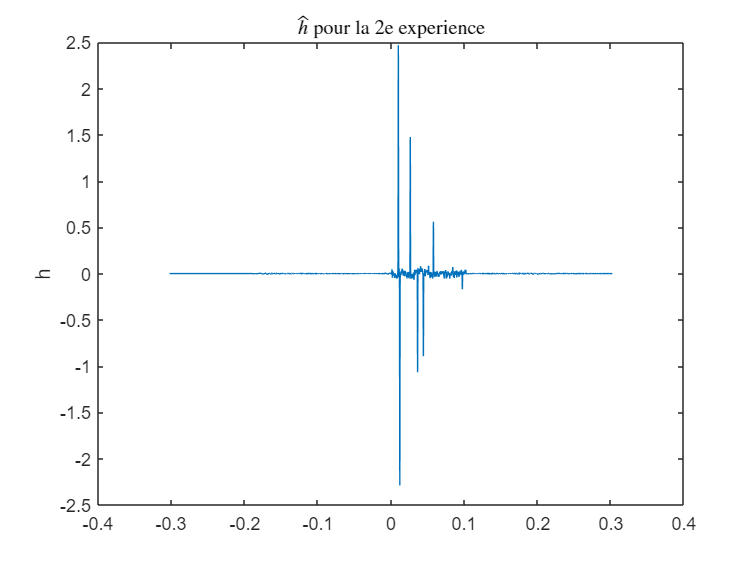

load Data.mat
T=0.2;
B=2000;
tk = 0:Ts:(N-1)*Ts;
xk = f(B,T,tk);
Rxy_exp2=xcorr(y_experience2,xk);
h_exp=Rxy_exp2/Rx(N);
n2_exp=length(h_exp);
figure(1)
plot(Ts*linspace(-n2_exp/2,n2_exp/2-1,n2_exp),h_exp);
ylabel('h');
title('$\hat{h}$ pour la 2e experience' ,'interpreter','latex');

c=(d3-d1)/(0.02625-0.00995);
fprintf('c= %s m/s',c)

c= 1.445153e+03 m/s

function a=tri(t)
if t<=1
    a=1-abs(t);
else
    a=0;
end
end
